# AFM Particle Detection and Alignment Walkthrough

% This live script demonstrates the steps of detecting and aligning particles
% in an AFM image using cross-correlation and rotational correction methods.

## Step 1: Load and Display Image

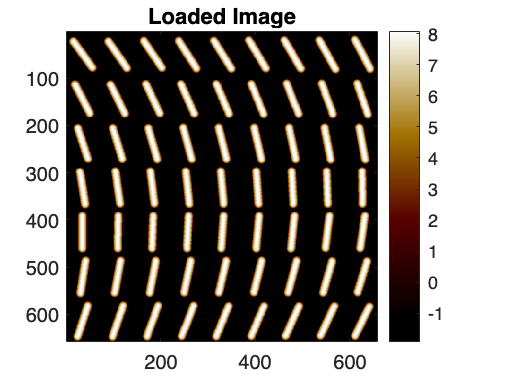

[im, ImageInfo] = ReadAFMFile('Rotate test.tif', 'Height');
d = im;

figure;
imagesc(d);
afm_colormap('AFM brown');
axis image;
title('Loaded Image');
colorbar;

## Step 2: Select Reference Particle

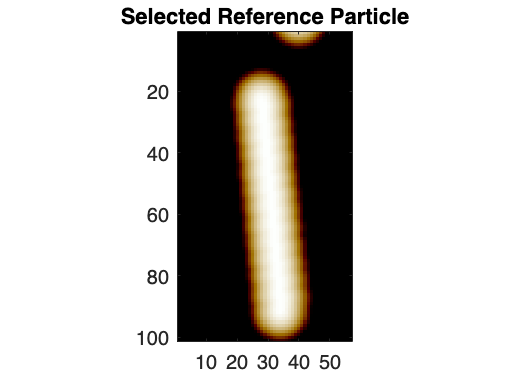

% Manually select a particle to use as reference by clicking on the image and pressing Enter.
ref = ref_selector(d);

figure;
imagesc(ref);
afm_colormap('AFM brown');
title('Selected Reference Particle');
axis image;

## Step 3: Detect Particles Using Cross-Correlation

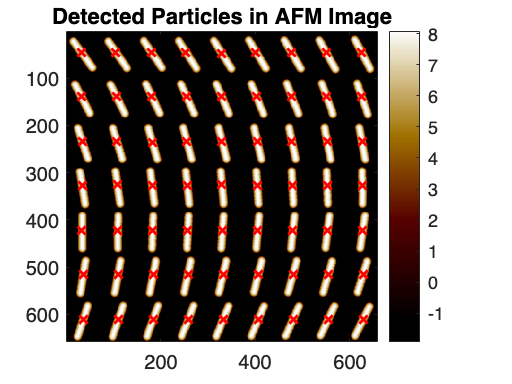

% Set parameters for particle detection and filtering
ccr_thresh = 0.8;    % Cross-correlation threshold
filt_img = 1;        % Image filtering
filt_ccr = 1;        % Cross-correlation image filtering
ex_edge = 0;         % Edge exclusion
angles = -40:10:40;  % Rotational search angles
fastdetect = 1;      % Fast detection option

[locs] = Detector(im, 'ccr', ref, filt_img, filt_ccr, ccr_thresh, ex_edge, fastdetect, angles);

figure;
imagesc(d);
hold on;
plot(locs(:,1), locs(:,2), 'rx', 'LineWidth', 1.5);
afm_colormap('AFM brown');
axis image;
title('Detected Particles in AFM Image');
colorbar;

## Step 4: Construct Particle Stack

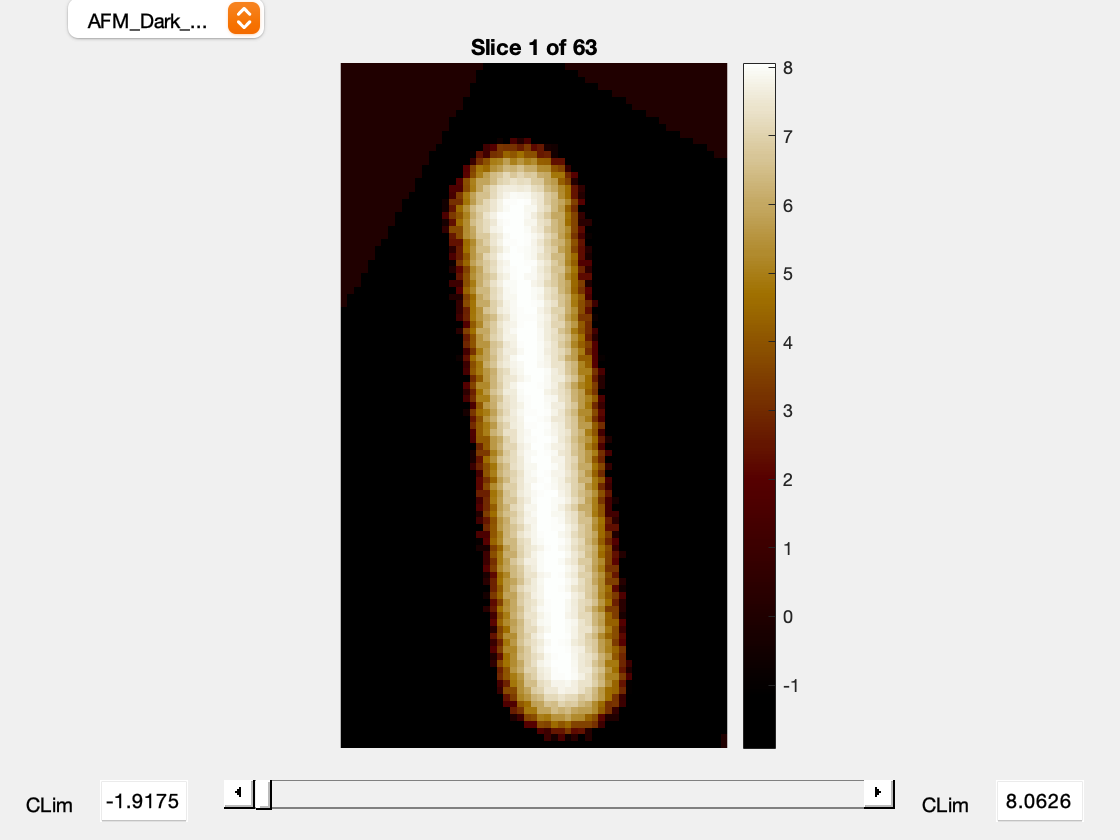

Part.Locs = locs;
Part.Image = ref;
Part.Image = ConstructParticleStack(d, Part, 1);

viewstack(Part.Image);

## Step 5: Align Particles

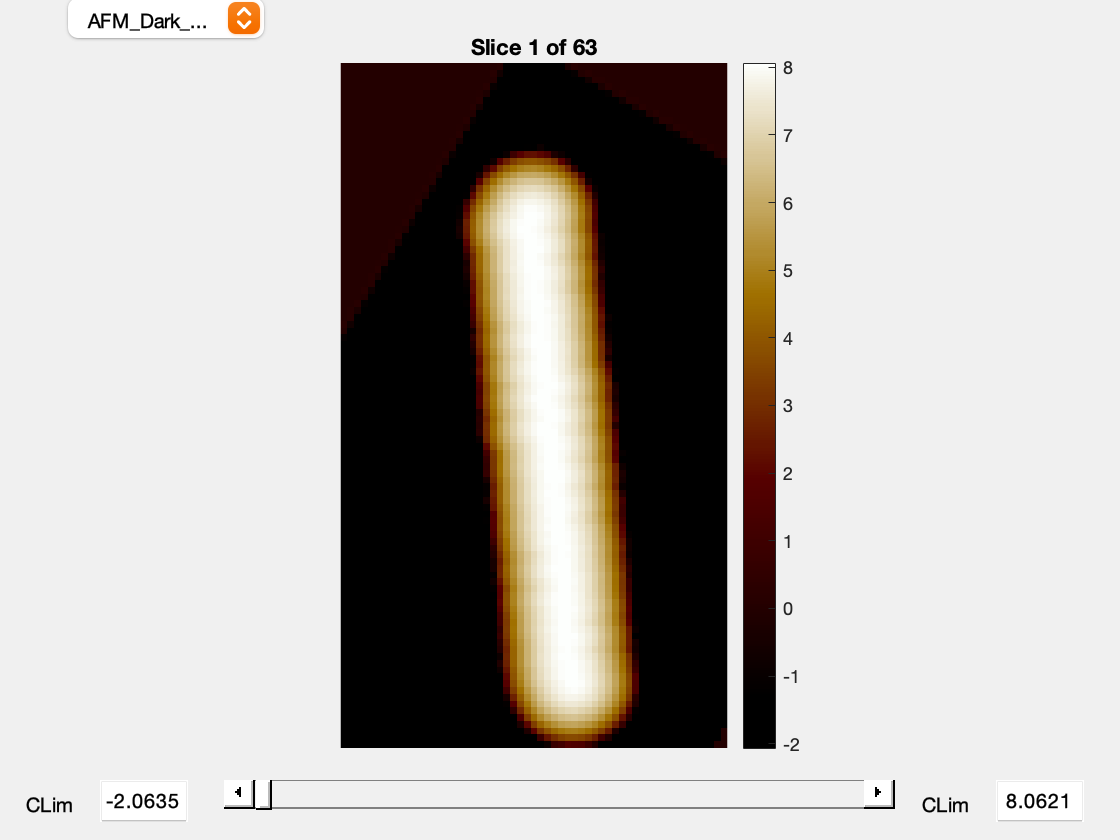

trans_iter = 2;      % Number translational alingment iterations
search_win = 10;     % +/- pixels
rotational_iter = 2; % Number rotational alingment iterations
rot_search_win = 10; % +/- degrees
Thresh_min = 1;      % Minimum z threshold for feature consideration
Autoupdateref = 1;   % Flag to auto-update the reference during iteration (true/false)

[Part, ref2] = align_iterate(d, ref, Part, ...
    trans_iter, 'FFT cross', search_win, ...
    rotational_iter, 'Rotation corr', rot_search_win, ...
    Thresh_min, Autoupdateref);
T = array2table(Part.Locs,'VariableNames',{'x','y','Height','ccr','Frame','id','Track id','Angle'});
viewstack(Part.Image);

## Step 6: Visualise Aligned Particles

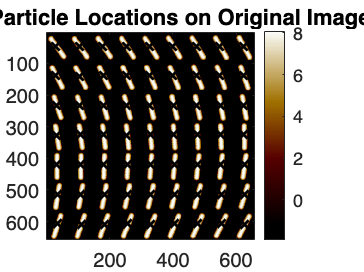

figure;
imagesc(d);
hold on;
plot(Part.Locs(:,1), Part.Locs(:,2), 'kx', 'LineWidth', 1.5);
afm_colormap('AFM brown');
axis image;
title('Final Particle Locations on Original Image');
colorbar;

T

T = 63×8 table
      x         y       Height      ccr      Frame    id    Track id     Angle 
    ______    ______    ______    _______    _____    __    ________    _______

     29.91      45.6    8.0291    0.90403      1      0        0        -30.778
     30.12    139.38    8.0203    0.90502      1      0        0        -21.972
      32.2    420.02    7.7138    0.89461      1      0        0         5.0528
     31.57    233.09    8.0319     0.9006      1      0        0        -13.452
     32.19    327.23    8.0341    0.91947      1      0        0        -3.9659
     34.62    514.61    8.0222    0.86942      1      0        0         14.207
     35.22    607.65    7.9787    0.86972      1      0        0        